clear variables

load leftPic.mat
load rightPic.mat

detectorObjects.blobAnalysis = vision.BlobAnalysis('BoundingBoxOutputPort', true,'AreaOutputPort', true,'CentroidOutputPort', true, ...
    'MinimumBlobArea', 200, 'MaximumBlobArea', 1000,'MaximumCount', 50,'PerimeterOutputPort',true);

tic
img = snapshot1;
[centroids_new, bbox_new] = detectBlobs(detectorObjects,img);
toc

历时 0.032399 秒。


tic
img1 = snapshot1;
img2 = snapshot2;
[centroids_new_1, bbox_new_1] = detectBlobs(detectorObjects,img1);
[centroids_new_2, bbox_new_2] = detectBlobs(detectorObjects,img2);
toc

历时 0.062816 秒。


tic
parfor i = 1:2
    if i == 1
        [centroids_new_1, bbox_new_1] = detectBlobs(detectorObjects,img1);
    else
        [centroids_new_2, bbox_new_2] = detectBlobs(detectorObjects,img2);
    end
end
toc

历时 0.186908 秒。


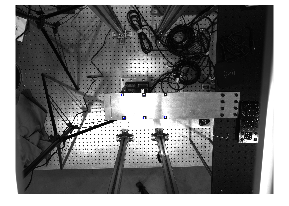

frame = insertShape(img,"rectangle",bbox_new,"LineWidth",4,"Color","blue");
imshow(frame)

function [centroids_new, bbox_new] = detectBlobs(detectorObjects, frame)
% Expected uncertainty (noise) for the blob centroid.

    frame_gray = im2gray(frame);
    fig_binarize = imbinarize(frame_gray,0.9);
    
    [area,centroids,bbox,Perimeter] = detectorObjects.blobAnalysis.step(fig_binarize);
    
    selectedBlobs = (3.5 <(Perimeter.^2)./(double(area)*pi)) & ((Perimeter.^2)./(double(area)*pi) < 4.5);
    bbox_new = bbox(selectedBlobs, :);
    centroids_new = centroids(selectedBlobs, :);
end